## For the outputs X(t) and theta_2(t) The observer is given as


M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

## A_f and B_f matrices

A_f =[0 1 0 0 0 0;0 0 (-m1*g)/M 0 (-m2*g)/M 0;0 0 0 1 0 0;0 0 -(g/l1)*((m1+M)/M) 0 (-m2*g)/M*l1 0;0 0 0 0 0 1;0 0 (-m1*g)/M*l2 0 -(g/l2)*((m2+M)/M) 0]

A_f =          0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0    1.0000         0         0
         0         0   -0.5396         0  -19.6200         0
         0         0         0         0         0    1.0000
         0         0   -9.8100         0   -1.0791         0


B_f =[0;1/M;0;1/(M*l1);0;1/(M*l2)]

B_f = 	1.0e+-3 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


eigs(A_f)

ans =   -0.0000 + 3.8322i
  -0.0000 - 3.8322i
  -3.6148 + 0.0000i
   3.6148 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


C = [1 0 0 0 0 0;0 0 0 0 1 0;]

C =      1     0     0     0     0     0
     0     0     0     0     1     0


D = [0;0]

D =      0
     0



plant = ss(A_f,B_f,C,D);
Plant_poles = pole(plant);

## Controllability Matrix and rank condition

Co = ctrb(plant);
rank_Co = rank(Co);

## Initial conditions

I = [0;1;1;0;1;0]

I =      0
     1
     1
     0
     1
     0


## Luenberger Observer Design 

%Luen_SYS = ss(A_f-L*C,B_f,C,D)
%step(Luen_SYS)

## Luenberger Observer Design 

Controllability Check - Rank condition of the observability matrix satisfies. Hence Observable

C_Lo = ctrb(A_f',C')

C_Lo =     1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0   -0.9810   -9.8100         0         0   10.1529   15.8790         0         0
         0         0         0         0         0         0   -0.9810   -9.8100         0         0   10.1529   15.8790
         0    1.0000         0         0   -0.9810   -1.0791         0         0   20.3058  193.6367         0         0
         0         0         0    1.0000         0         0   -0.9810   -1.0791         0         0   20.3058  193.6367


rak_ctrb1 = rank(C_Lo)

rak_ctrb1 = 6

Ob_Lo = obsv(A_f,C)

Ob_Lo =     1.0000         0         0         0         0         0
         0         0         0         0    1.0000         0
         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000
         0         0   -0.9810         0   -0.9810         0
         0         0   -9.8100         0   -1.0791         0
         0         0         0   -0.9810         0   -0.9810
         0         0         0   -9.8100         0   -1.0791
         0         0   10.1529         0   20.3058         0
         0         0   15.8790         0  193.6367         0


rank_Obsv1 = rank(Ob_Lo)

rank_Obsv1 = 6

pole(Plant_LQR)

ans =  -14.5859 +13.6057i
 -14.5859 -13.6057i
  -2.1921 + 3.6421i
  -2.1921 - 3.6421i
  -5.5397 + 0.0000i
  -3.6311 + 0.0000i


Poles_L_Obs = [-28;-30;-10;-6;-2;-4]

Poles_L_Obs =    -28
   -30
   -10
    -6
    -2
    -4




L = place(A_f',C',Poles_L_Obs)'

L =    34.2743    0.8932
  174.7915   36.8658
  -37.6817 -208.5662
  -47.2669 -228.2706
    1.2047   45.7257
   56.7906  537.4500



Luen_SYS = ss(A_f-L*C,B_f,C,D)


Luen_SYS =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1   -34.27        1        0        0  -0.8932        0
   x2   -174.8        0   -0.981        0   -37.85        0
   x3    37.68        0        0        1    208.6        0
   x4    47.27        0  -0.5396        0    208.7        0
   x5   -1.205        0        0        0   -45.73        1
   x6   -56.79        0    -9.81        0   -538.5        0
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



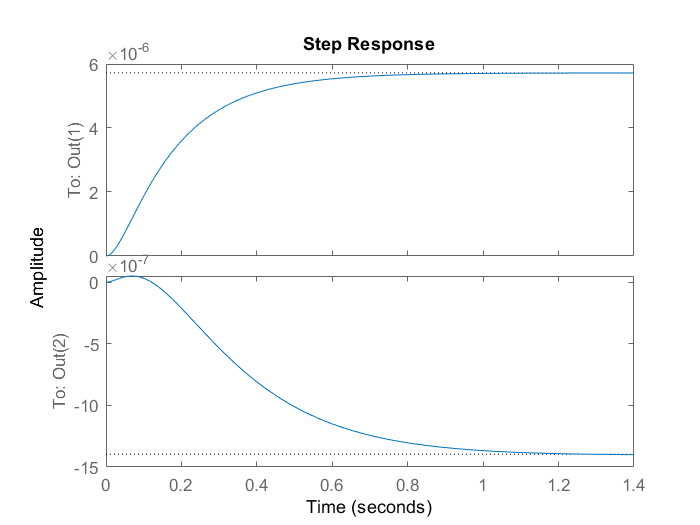

step(Luen_SYS)